# Savitzky-Golay Filtering

A program which is developed based on Savitzky-Golay approach for smoothing rate-normalized pressure (RNP) data.

Author: Munthe, Felix A.

Created on Monday, 30 October 2023

## Import Data

### True RNP Data

clear; clc; clf;
opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["t", "RNP"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
true_RNP = readtable("C:\Users\ASUS\Documents\Kuliah\2. Master's Texas A&M University\Publications\Conference Paper\Smoothing Paper\Smoothing Simulator\true_RNP.txt", opts)

true_RNP = 1150×2 table
       t          RNP    
    _______    __________

       0.25    1.3616e+06
    0.33041    1.9565e+06
     0.4862    2.6089e+06
    0.79777    3.4782e+06
     1.4209    4.6953e+06
     2.6672    6.4232e+06
     5.0773    8.8236e+06
     9.8974    1.2258e+07
     19.198    1.7054e+07
     35.645    2.3347e+07
      66.06    3.1893e+07
     124.99    4.3906e+07
     188.99    5.4925e+07
     252.99    6.4572e+07
     316.99    7.3193e+07
     380.99     8.103e+07


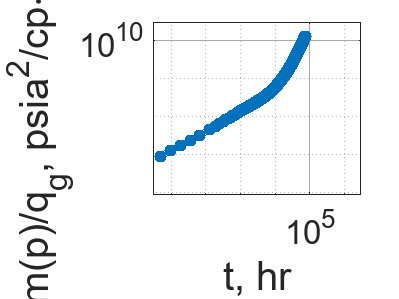


% Plot
loglog(true_RNP.t, true_RNP.RNP, ".", "MarkerSize", 25,"Color", "#0072BD");
% title("True RNP Data", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold off;

### Noisy RNP Data Set 193

opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["t", "RNP"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
noisy_RNP_193 = readtable("C:\Users\ASUS\Documents\Kuliah\2. Master's Texas A&M University\Publications\Conference Paper\Smoothing Paper\Smoothing Simulator\Noisy RNP Model\All\50%\noisy_data_3.txt", opts)

noisy_RNP_193 = 1150×2 table
       t          RNP    
    _______    __________

       0.25    7.5763e+07
    0.33041    1.9565e+06
     0.4862    2.6089e+06
    0.79777    1.6825e+08
     1.4209    4.6953e+06
     2.6672    6.4232e+06
     5.0773    8.8236e+06
     9.8974      5.54e+06
     19.198    2.0613e+08
     35.645    2.1996e+08
      66.06    2.5903e+08
     124.99    4.3906e+07
     188.99    3.0087e+08
     252.99    9.8883e+07
     316.99    7.3193e+07
     380.99     8.103e+07


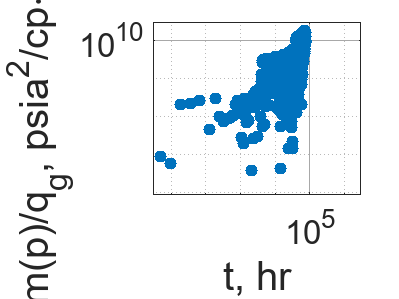


% Plot
loglog(noisy_RNP_193.t, noisy_RNP_193.RNP, ".", "MarkerSize", 25,"Color", "#0072BD");
% title("Noisy RNP Data Set 193", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold off;

## Smoothing

### Noisy RNP Data 193

logRNP_193 = log(noisy_RNP_193.RNP);

#### Window: 3

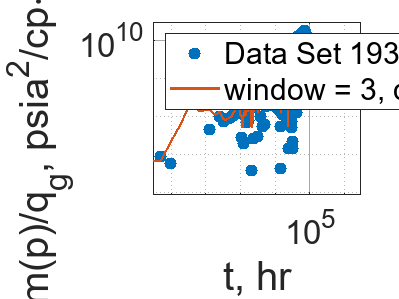

% Plot
loglog(noisy_RNP_193.t, noisy_RNP_193.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 193");
% title("Noisy RNP Data Set 193", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

% Degree = 1
smoothedLogRNP_193_31 = smooth(logRNP_193, 3, "sgolay", 1);
smoothedRNP_193_31 = exp(smoothedLogRNP_193_31);
residual_193_31 = (true_RNP.RNP - smoothedRNP_193_31) ./ (0.3413 .* true_RNP.RNP);
sse_193_31 = sum(residual_193_31 .^ 2);
loglog(noisy_RNP_193.t, smoothedRNP_193_31, "-", "LineWidth", 1.3, "DisplayName", "window = 3, degree = 1");
legend("Location", "northwest");
hold off;

### Window: 5

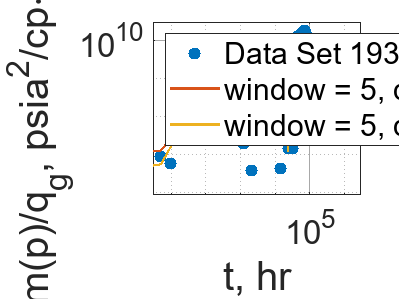

% Plot
loglog(noisy_RNP_193.t, noisy_RNP_193.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 193");
% title("Noisy RNP Data Set 193", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

% Degree = 1
smoothedLogRNP_193_51 = smooth(logRNP_193, 5, "sgolay", 1);
smoothedRNP_193_51 = exp(smoothedLogRNP_193_51);
residual_193_51 = (true_RNP.RNP - smoothedRNP_193_51) ./ (0.3413 .* true_RNP.RNP);
sse_193_51 = sum(residual_193_51 .^ 2);
loglog(noisy_RNP_193.t, smoothedRNP_193_51, "-", "LineWidth", 1.3, "DisplayName", "window = 5, degree = 1");
hold on;

% Degree = 2
smoothedLogRNP_193_52 = smooth(logRNP_193, 5, "sgolay", 2);
smoothedRNP_193_52 = exp(smoothedLogRNP_193_52);
residual_193_52 = (true_RNP.RNP - smoothedRNP_193_52) ./ (0.3413 .* true_RNP.RNP);
sse_193_52 = sum(residual_193_52 .^ 2);
loglog(noisy_RNP_193.t, smoothedRNP_193_52, "-", "LineWidth", 1.3, "DisplayName", "window = 5, degree = 2");
legend("Location", "northwest");
hold off;

#### Window: 7

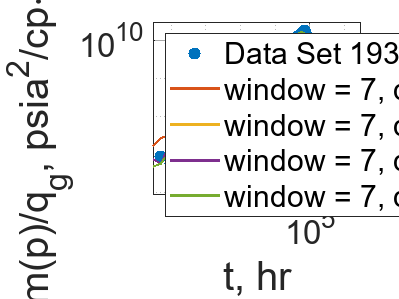

% Plot
loglog(noisy_RNP_193.t, noisy_RNP_193.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 193");
% title("Noisy RNP Data Set 193", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

% Degree = 1
smoothedLogRNP_193_71 = smooth(logRNP_193, 7, "sgolay", 1);
smoothedRNP_193_71 = exp(smoothedLogRNP_193_71);
residual_193_71 = (true_RNP.RNP - smoothedRNP_193_71) ./ (0.3413 .* true_RNP.RNP);
sse_193_71 = sum(residual_193_71 .^ 2);
loglog(noisy_RNP_193.t, smoothedRNP_193_71, "-", "LineWidth", 1.3, "DisplayName", "window = 7, degree = 1");
hold on;

% Degree = 2
smoothedLogRNP_193_72 = smooth(logRNP_193, 7, "sgolay", 2);
smoothedRNP_193_72 = exp(smoothedLogRNP_193_72);
residual_193_72 = (true_RNP.RNP - smoothedRNP_193_72) ./ (0.3413 .* true_RNP.RNP);
sse_193_72 = sum(residual_193_72 .^ 2);
loglog(noisy_RNP_193.t, smoothedRNP_193_72, "-", "LineWidth", 1.3, "DisplayName", "window = 7, degree = 2");
hold on;

% Degree = 3
smoothedLogRNP_193_73 = smooth(logRNP_193, 7, "sgolay", 3);
smoothedRNP_193_73 = exp(smoothedLogRNP_193_73);
residual_193_73 = (true_RNP.RNP - smoothedRNP_193_73) ./ (0.3413 .* true_RNP.RNP);
sse_193_73 = sum(residual_193_73 .^ 2);
loglog(noisy_RNP_193.t, smoothedRNP_193_73, "-", "LineWidth", 1.3, "DisplayName", "window = 7, degree = 3");
hold on;

% Degree = 4
smoothedLogRNP_193_74 = smooth(logRNP_193, 7, "sgolay", 4);
smoothedRNP_193_74 = exp(smoothedLogRNP_193_74);
residual_193_74 = (true_RNP.RNP - smoothedRNP_193_74) ./ (0.3413 .* true_RNP.RNP);
sse_193_74 = sum(residual_193_74 .^ 2);
loglog(noisy_RNP_193.t, smoothedRNP_193_74, "-", "LineWidth", 1.3, "DisplayName", "window = 7, degree = 4");
legend("Location", "northwest");
hold off;

#### Window: 9

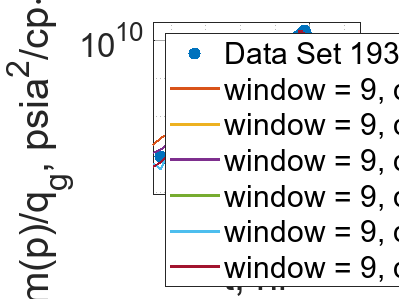

% Plot
loglog(noisy_RNP_193.t, noisy_RNP_193.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 193");
% title("Noisy RNP Data Set 193", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

% Degree = 1
smoothedLogRNP_193_91 = smooth(logRNP_193, 9, "sgolay", 1);
smoothedRNP_193_91 = exp(smoothedLogRNP_193_91);
residual_193_91 = (true_RNP.RNP - smoothedRNP_193_91) ./ (0.3413 .* true_RNP.RNP);
sse_193_91 = sum(residual_193_91 .^ 2);
loglog(noisy_RNP_193.t, smoothedRNP_193_91, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 1");
hold on;

% Degree = 2
smoothedLogRNP_193_92 = smooth(logRNP_193, 9, "sgolay", 2);
smoothedRNP_193_92 = exp(smoothedLogRNP_193_92);
residual_193_92 = (true_RNP.RNP - smoothedRNP_193_92) ./ (0.3413 .* true_RNP.RNP);
sse_193_92 = sum(residual_193_92 .^ 2);
loglog(noisy_RNP_193.t, smoothedRNP_193_92, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 2");
hold on;

% Degree = 3
smoothedLogRNP_193_93 = smooth(logRNP_193, 9, "sgolay", 3);
smoothedRNP_193_93 = exp(smoothedLogRNP_193_93);
residual_193_93 = (true_RNP.RNP - smoothedRNP_193_93) ./ (0.3413 .* true_RNP.RNP);
sse_193_93 = sum(residual_193_93 .^ 2);
loglog(noisy_RNP_193.t, smoothedRNP_193_93, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 3");
hold on;

% Degree = 4
smoothedLogRNP_193_94 = smooth(logRNP_193, 9, "sgolay", 4);
smoothedRNP_193_94 = exp(smoothedLogRNP_193_94);
residual_193_94 = (true_RNP.RNP - smoothedRNP_193_94) ./ (0.3413 .* true_RNP.RNP);
sse_193_94 = sum(residual_193_94 .^ 2);
loglog(noisy_RNP_193.t, smoothedRNP_193_94, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 4");
hold on;

% Degree = 5
smoothedLogRNP_193_95 = smooth(logRNP_193, 9, "sgolay", 5);
smoothedRNP_193_95 = exp(smoothedLogRNP_193_95);
residual_193_95 = (true_RNP.RNP - smoothedRNP_193_95) ./ (0.3413 .* true_RNP.RNP);
sse_193_95 = sum(residual_193_95 .^ 2);
loglog(noisy_RNP_193.t, smoothedRNP_193_95, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 5");
hold on;

% Degree = 6
smoothedLogRNP_193_96 = smooth(logRNP_193, 9, "sgolay", 6);
smoothedRNP_193_96 = exp(smoothedLogRNP_193_96);
residual_193_96 = (true_RNP.RNP - smoothedRNP_193_96) ./ (0.3413 .* true_RNP.RNP);
sse_193_96 = sum(residual_193_96 .^ 2);
loglog(noisy_RNP_193.t, smoothedRNP_193_96, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 6");
legend("Location", "northwest");
hold off;

#### Window: 11

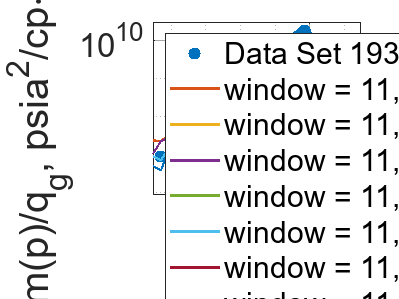

% Plot
loglog(noisy_RNP_193.t, noisy_RNP_193.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 193");
% title("Noisy RNP Data Set 193", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

% Degree = 1
smoothedLogRNP_193_111 = smooth(logRNP_193, 11, "sgolay", 1);
smoothedRNP_193_111 = exp(smoothedLogRNP_193_111);
residual_193_111 = (true_RNP.RNP - smoothedRNP_193_111) ./ (0.3413 .* true_RNP.RNP);
sse_193_111 = sum(residual_193_111 .^ 2);
loglog(noisy_RNP_193.t, smoothedRNP_193_111, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 1");
hold on;

% Degree = 2
smoothedLogRNP_193_112 = smooth(logRNP_193, 11, "sgolay", 2);
smoothedRNP_193_112 = exp(smoothedLogRNP_193_112);
residual_193_112 = (true_RNP.RNP - smoothedRNP_193_112) ./ (0.3413 .* true_RNP.RNP);
sse_193_112 = sum(residual_193_112 .^ 2);
loglog(noisy_RNP_193.t, smoothedRNP_193_112, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 2");
hold on;

% Degree = 3
smoothedLogRNP_193_113 = smooth(logRNP_193, 11, "sgolay", 3);
smoothedRNP_193_113 = exp(smoothedLogRNP_193_113);
residual_193_113 = (true_RNP.RNP - smoothedRNP_193_113) ./ (0.3413 .* true_RNP.RNP);
sse_193_113 = sum(residual_193_113 .^ 2);
loglog(noisy_RNP_193.t, smoothedRNP_193_113, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 3");
hold on;

% Degree = 4
smoothedLogRNP_193_114 = smooth(logRNP_193, 11, "sgolay", 4);
smoothedRNP_193_114 = exp(smoothedLogRNP_193_114);
residual_193_114 = (true_RNP.RNP - smoothedRNP_193_114) ./ (0.3413 .* true_RNP.RNP);
sse_193_114 = sum(residual_193_114 .^ 2);
loglog(noisy_RNP_193.t, smoothedRNP_193_114, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 4");
hold on;

% Degree = 5
smoothedLogRNP_193_115 = smooth(logRNP_193, 11, "sgolay", 5);
smoothedRNP_193_115 = exp(smoothedLogRNP_193_115);
residual_193_115 = (true_RNP.RNP - smoothedRNP_193_115) ./ (0.3413 .* true_RNP.RNP);
sse_193_115 = sum(residual_193_115 .^ 2);
loglog(noisy_RNP_193.t, smoothedRNP_193_115, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 5");
hold on;

% Degree = 6
smoothedLogRNP_193_116 = smooth(logRNP_193, 11, "sgolay", 6);
smoothedRNP_193_116 = exp(smoothedLogRNP_193_116);
residual_193_116 = (true_RNP.RNP - smoothedRNP_193_116) ./ (0.3413 .* true_RNP.RNP);
sse_193_116 = sum(residual_193_116 .^ 2);
loglog(noisy_RNP_193.t, smoothedRNP_193_116, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 6");
hold on;

% Degree = 7
smoothedLogRNP_193_117 = smooth(logRNP_193, 11, "sgolay", 7);
smoothedRNP_193_117 = exp(smoothedLogRNP_193_117);
residual_193_117 = (true_RNP.RNP - smoothedRNP_193_117) ./ (0.3413 .* true_RNP.RNP);
sse_193_117 = sum(residual_193_117 .^ 2);
loglog(noisy_RNP_193.t, smoothedRNP_193_117, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 7");
legend("Location", "northwest");
hold off;